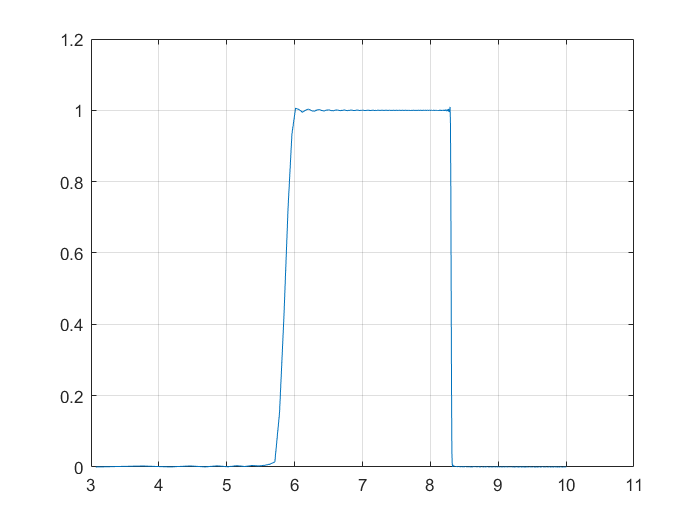

[x,fs] = audioread('lovesong_demo.wav');
%sound(x,fs); 
x_L = x(:,1);
x_R = x(:,2);


fcuts = [300 400 4000 4100];
mags = [0 1 0];
devs = [0.01 0.05 0.01];

[n,Wn,beta,ftype] = kaiserord(fcuts,mags,devs,fs);
n = n + rem(n,2);
hh1 = fir1(n,Wn,ftype,kaiser(n+1,beta),'noscale');

[H,f] = freqz(hh1,1,1024,fs);
plot(log(f),abs(H))
grid

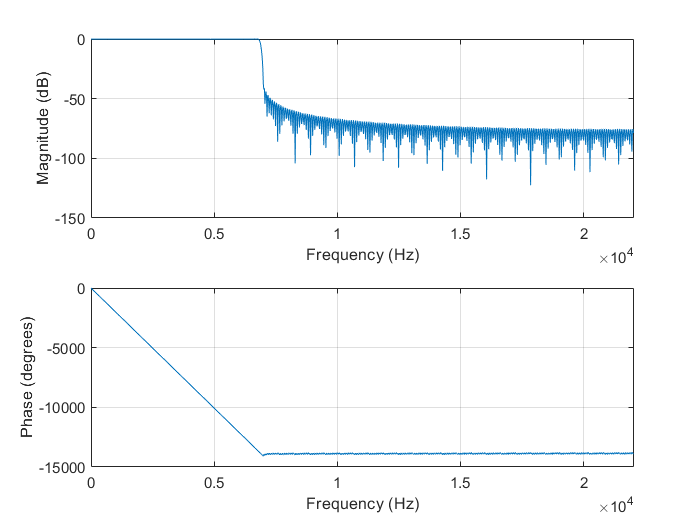


C = conv(x_L,hh1,'same')+conv(x_R,hh1,'same');
%sound(C/2,fs);

RL = delayseq(x_L,15e-3,fs);
RR = delayseq(x_R,15e-3,fs);

fcuts = [6800 7000];
mags = [1 0];
devs = [0.05 0.01];

[n,Wn,beta,ftype] = kaiserord(fcuts,mags,devs,fs);
hh2 = fir1(n,Wn,ftype,kaiser(n+1,beta),'noscale');

freqz(hh2,1,1024,fs)

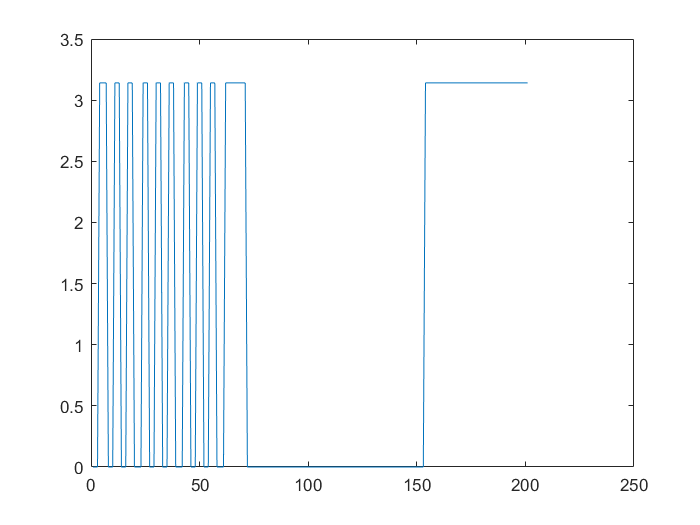


RL = conv(RL,hh2,'same');
RR = conv(RR,hh2,'same');
%sound(RL,fs)
figure
plot(angle(RL(600:800)))

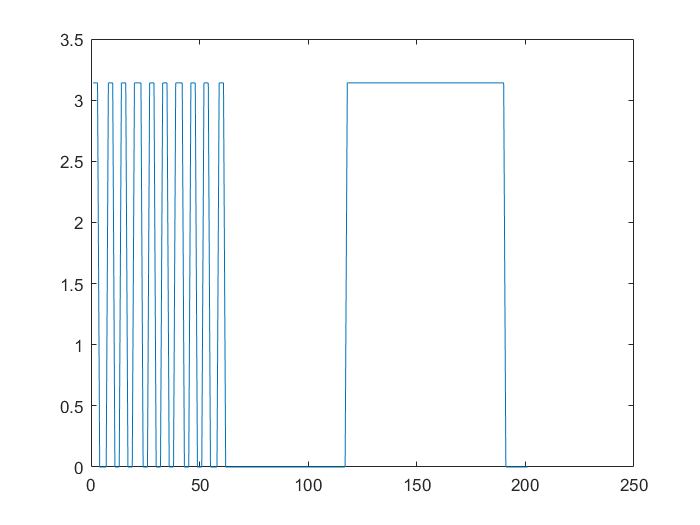


X_hibert = hilbert(RR);
RR_hibert = imag(X_hibert);

RR_180 = hilbert(RR_hibert);
RR = imag(RR_180);
%RR = delayseq(RL,1/2/fs,fs);
%sound(RR,fs)
figure
plot(angle(RR(600:800)))

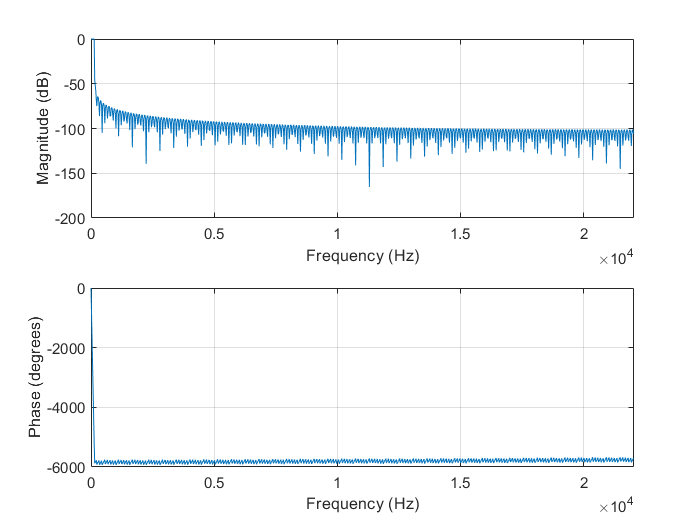


fcuts = [140 150];
mags = [1 0];
devs = [0.05 0.01];

[n,Wn,beta,ftype] = kaiserord(fcuts,mags,devs,fs);
hh3 = fir1(n,Wn,ftype,kaiser(n+1,beta),'noscale');
freqz(hh3,1,1024,fs)

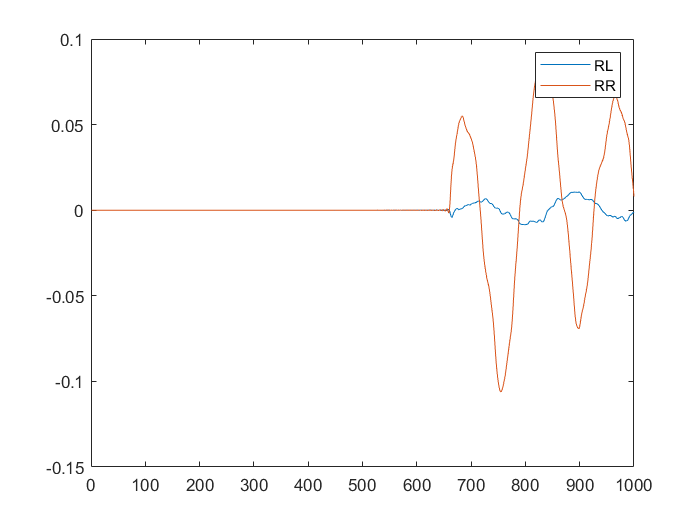


LFE = conv(x_L,hh3,'same')+conv(x_R,hh3,'same');
%sound(LFE,fs)

figure
plot(RL(1:1000))
hold on 
plot(RR(1:1000))
hold off
legend('RL','RR')


x_origin = [];
x_new = [RL,RR];
%sound(x_new,fs);
x_all = [(RL*2+x_L*6+C*4+LFE*3)/4, (RR*2+x_R*6+C*4+LFE*3)/4];

audiowrite('lovesong_demo_RRRL.wav',x_new,fs);

Error using audiowrite (line 203)
Unsupported number of channels.

audiowrite('lovesong_demo_LFE.wav',LFE,fs);
audiowrite('lovesong_demo_C.wav',C/2,fs);
audiowrite('lovesong_demo_x_all.wav',x_all/2,fs);
